# **IO821 - Time Interrupt**

This example shows you how to set up your model using the interrupt from the IO821 I/O module, in order to periodically read the time form the module at the desired rate. 

The IO821 I/O module (with an optional GNSS (GPS/GLONASS) receiver) provides precision timing and synchronization for real-time applications and includes both IRIG and 1PPS input and output interfaces. The precision timing reference uses a 5 ns-resolution onboard oscillator that is phase-locked to an external timing reference input.

The Simulink model features the [IO821 Time Reference](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io821_time_reference) and [IO821 Read Interrupt](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io821_read_interrupt) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO821 I/O module installed

### Test Setup

In this example, the self-reference mode is used and therefore no external wiring is required. The IO821 runs on the internal oscillator, initialized by the [datenum](https://www.mathworks.com/help/matlab/ref/datetime.datenum.html) value set in the **Initial Module Time** parameter.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO821_TimeInterrupt';
open_system(modelName);

% Set fundamental sample time
set_param(modelName, 'FixedStep', '1.0');

### Model Description

In the model, the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block is configured to trigger the model based on the periodic interrupt from the IO821. The [Read Interrupt](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io821_read_interrupt) block is needed to handle the interrupt. It allows as well to detect the source of the interrupt.

The [Time Reference](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io821_time_reference) block configures the IO821 and allows to read the time and various status outputs. The sync status output shows if the onboard oscillator is synchronized, which is the case when the configured time and 1PPS reference is valid. The holdover status output shows if the configured time and/or PPS input has been lost for a certain time. The time output is configured to use the MATLAB [datenum](https://www.mathworks.com/help/matlab/ref/datetime.datenum.html) format and the fraction of a second to indicate the current time.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the time output is valid, the sync state must be one and the holdover state must be zero. In the second scope, the time signal must be displayed in the [datenum](https://www.mathworks.com/help/matlab/ref/datetime.datenum.html) format, which increases by one second every time the model is triggered by the IO821 interrupt.

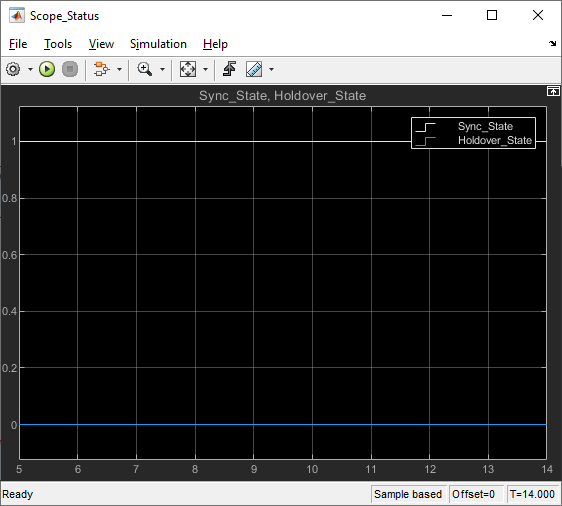

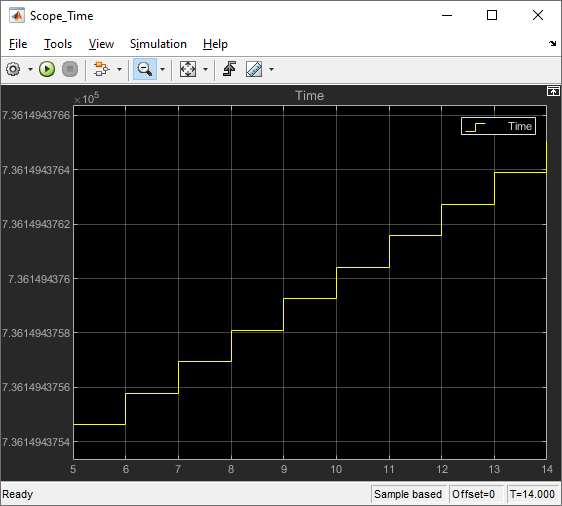

## Additional References

- [IO821 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io821)